## Problema 1

Se analizează teoretic și comparativ algortimul bazat pe interpolarea în forma Newton și algoritmul bazat pe interpolarea baricentrică.

### Algoritmul bazat pe forma Newton

Luăm forma generală a formei Newton a polinomului de interpolare a lui Lagrange, considerăm $m$ numărul punctelor în care funcția este dată:

$\left(L_m f\right)\left(x\right)=f\left(x_0 \right)+\sum_{k=1}^m f\left\lbrack x_0 ,x_1 ,\ldotp \ldotp \ldotp ,x_k \right\rbrack \left(x-x_0 \right)\left(x-x_1 \right)\ldotp \ldotp \ldotp \left(x-x_{k-1} \right)$. Precalculăm diferențele divizate și obținem: 

- Pentru diferențele divizate de ordinul I nu avem complexitate, deoarece acestea sunt valorile funcției date

- De la grad mai mare sau egal cu II complexitatea calculării unei diferențe divizate va fi de 3 FLOPS (2 scăderi, 1 împărțire), avem de calculat $\frac{\left(m-1\right)\left(m-1+1\right)}{2}=\frac{m\left(m-1\right)}{2}$ FLOPS

Pentru evaluare vom ține precalculat într-o variabilă produsul $p_k =\prod_{i=0}^{k-1} \left(x-x_i \right)$ necesar la pasul $k$, se poate deduce rapid formula de recurență $p_k =p_{k-1} *\left(x-x_{k-1} \right)$ calculat până la pasul respectiv, așadar la fiecare pas vom avea de făcut 4 FLOPS (una pentru evaluarea înmulțirii dintre diferența divizată și $p_k$, o operație pentru adunarea rezultatului la rezultatul global, și încă două operații pentru trecerea de la $p_k \;\mathrm{la}\;p_{k+1}$(o scădere și o înmulțirea)) astfel vom avea $4m$ operații flotante pentru evaluarea polinomului în fiecare punct. Asta ne conduce la o complexitate totală de $\frac{m\left(m-1\right)}{2}+4m=\frac{1}{2}\left(m^2 +3m\right)\;\mathrm{FLOPS}\approx O\left(m^2 \right)$ .

### Algoritmul bazat pe Ponderi baricentrice

Pentru calculul ponderilor baricentrice avem formula $w_j =\frac{1}{\prod_{k=1,k\not= j}^m \left(x_j -x_k \right)\;}$, ce are numitorul ce se poate calcul folosind $m-1$FLOPS pentru scăderi și $m-2$FLOPS pentru înmulțiri, în total $2m-3$FLOPS, acest lucru trebuie făcut pentru $\nabla j=\overline{1,m}$ deci avem $m*\left(2m-3\right)=m^2 -3m\;\mathrm{FLOPS}\;\mathrm{pentru}\;\mathrm{calculul}$ponderilor baricentrice. 

Pentru evaluare avem de calculat $\frac{\sum_{j=0}^m \frac{w_j }{x-x_j }*f_j }{\sum_{j=0}^m \frac{w_j }{x-x_j }}$ asta înseamnă 3 FLOPS pentru fiecare termen al sumei de la numărător (1 pentru scădere, 1 pentru împarțire, 1 pentru înmulțire), calculând asta de $m\;\mathrm{ori}$avem $3m$ operații, în timp ce în mod asemnănător putem observa că la numărător avem $2m$operații. Complxitatea totală pentru evaluarea într-un punct este $5m$, complexitatea totală fiind $m^2 -3m+5m=m^2 +2m\;\mathrm{FLOPS}\approx O\left(m^2 \right)$

## Problema 2

### a)

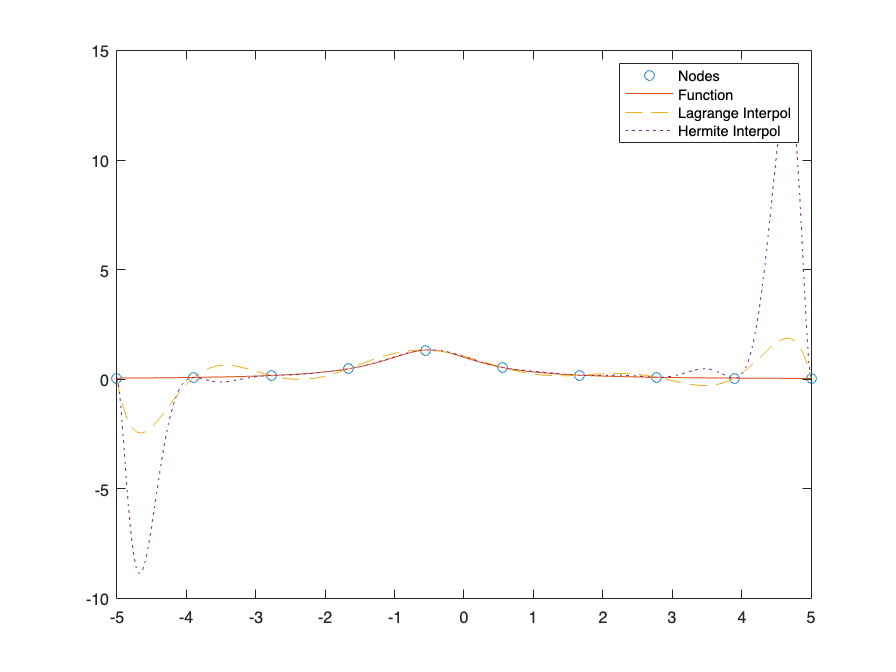

close all;
x = linspace(-5, 5, 10);
f = @(x) 1 ./ (1 + x + x.^2);
y = 1 ./ (1 + x + x.^2);
yd = -(2*x + 1) ./ ((1 + x + x .^ 2) .^ 2);

%points for evaluation
evalPoints = linspace(-5, 5, 300);

lagrangeApproximation = barycentricLagrange(x, y, evalPoints);
hermiteApproximation = Hermite(x, y, yd, evalPoints);

plot(x, y, 'o', evalPoints, f(evalPoints), evalPoints, lagrangeApproximation, '--', evalPoints, hermiteApproximation, ':')
legend('Nodes', 'Function', 'Lagrange Interpol', 'Hermite Interpol')

### b)

Evaluarea in 1/2

t = 1/2;

barycentricLagrange(x, y, t)

ans =    0.585653103224081


Hermite(x, y, yd, t)

ans =    0.572226107989725


f(t)

ans =    0.571428571428571


### c)

Eroarea teoretica

Lagrange

syms a xsi
g = @(a) 1/(1 + a + a ^ 2);
deriv(a) = diff(g, a, 11);
err = prod(a - x)/factorial(11) * deriv(xsi)

Hermite

err = prod((a - x).^2)/factorial(11) * deriv(xsi)

Eroarea practica 

mean(abs(f(evalPoints) - lagrangeApproximation))

ans =    0.396188231710212


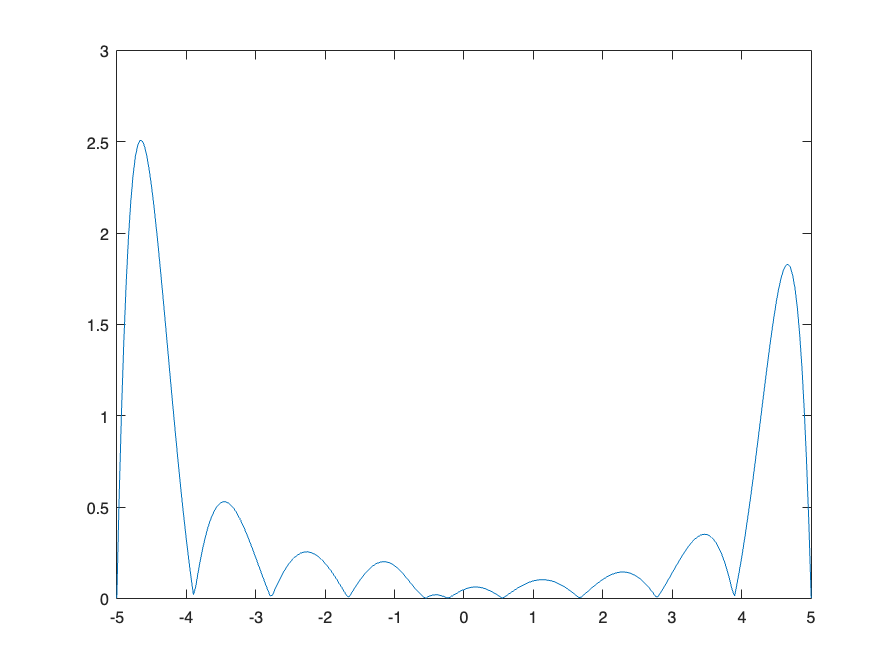

plot(evalPoints, (abs(f(evalPoints) - lagrangeApproximation)))

mean(abs(f(evalPoints) - hermiteApproximation))

ans =    1.124058313804981


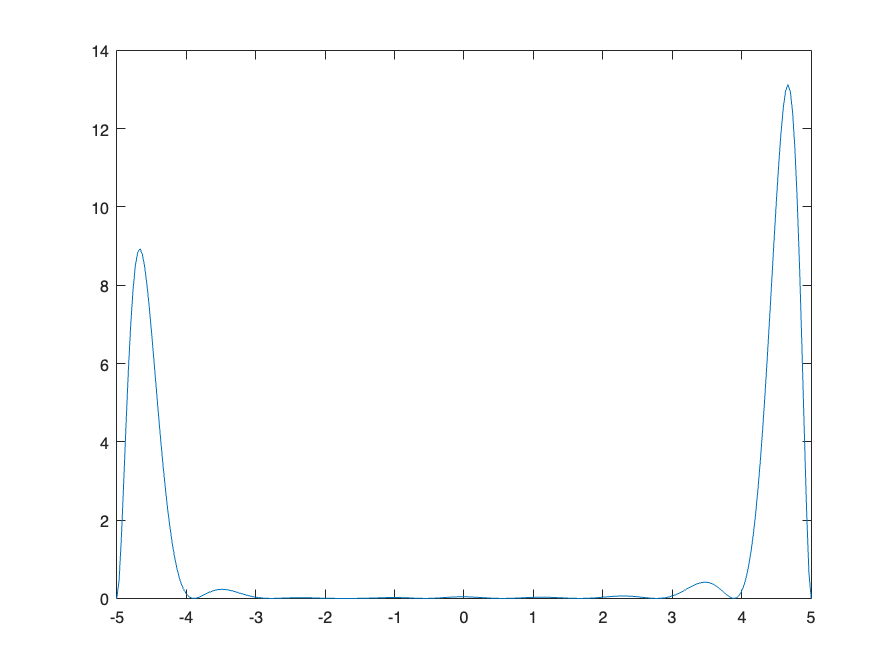

plot(evalPoints, (abs(f(evalPoints) - hermiteApproximation)))